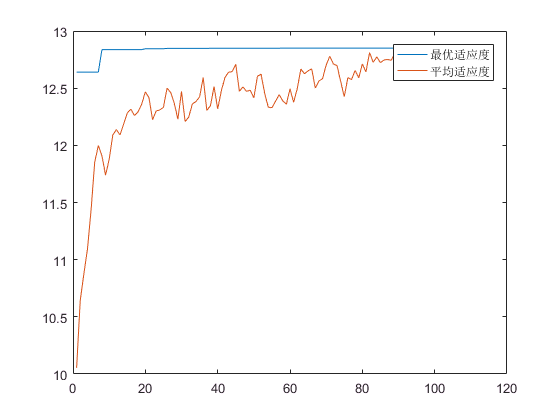

clc,clear,close all

%%%种群信息
N=100; %种群样本
iter=100; %迭代次数
ChromNum=1; %染色体节点数
inter=[0 3]; %染色体值区间

Chrom=zeros(N,ChromNum); %种群个体染色体
BestChrom=zeros(1,ChromNum+1); %种群最优染色体
EveryBest=zeros(1,iter+1); %所有代中的最优适应度
ChromFitness=zeros(N,1); %每一代种群的适应度
AvaFit=zeros(1,iter+1); %平均适应度

%%%概率信息
PCross=0.3;
PMul=0.1;

%%%初始化种群
Chrom=ProductChrom(N,ChromNum,inter);
ChromFitness=Fitness(Chrom);
BestChrom=FindBest(ChromFitness,Chrom);
EveryBest(1)=BestChrom(ChromNum+1);
AvaFit(1)=sum(ChromFitness)/N;

%%%迭代
for i=1:iter
    %%%自然选择(最优)
    [Chrom,~]=Select(Chrom,ChromFitness,N);
    
    %%%基因重组
    Chrom=Cross(Chrom,PCross,inter);
    
    %%%基因变异
    Chrom=Tation(Chrom,PMul,iter,i,inter);
    
    %%%计算适应度
    ChromFitness=Fitness(Chrom);
    
    %%%寻找最优\劣染色体
    NewBestChrom=FindBest(ChromFitness,Chrom);
    [WorseChrom,WorseIndex]=FindWorse(ChromFitness,Chrom);
    
    %%%代替上一次中最好的染色体
    if NewBestChrom(ChromNum+1)>BestChrom(ChromNum+1)
        BestChrom=NewBestChrom;
    end
    
    %%%替换掉最劣的
    Chrom(WorseIndex,:)=BestChrom(1:ChromNum);
    ChromFitness(WorseIndex)=BestChrom(ChromNum+1);
    
    %%%记录每一代的最好适应度和平均适应度
    AvaFit(i+1)=sum(ChromFitness)/N;
    EveryBest(i+1)=BestChrom(ChromNum+1);
end

%%%作图
X=1:iter+1;
figure(2)
plot(X,EveryBest);
hold on
plot(X,AvaFit);
legend('最优适应度','平均适应度')